# IMU calibration

## Overview

As it is known, no sensor is completely accurate, all of them suffer from different kind of noise or distortion effects. For a standard inertial measurement unit (IMU) this looks like the following:

### Gyroscope

For many sensors, including gyroscopes, the noise can be modeled as a constant (or slowly varying) and a random part, that changes each measurement. This can be modeled as normally distributed random variable, with the expected value being the constant, which in this field is often refered to as bias. With notation: $\eta \in \mathcal{N}(b,\sigma)$. Further problems can be caused by the fact that the axis of the sensor in reality might be slightly misaligned, but for this application we don't consider it.

Thus the measurement equations can be written as:

- 
$$\tilde{\omega}_x = \omega_x + \eta_x$$


- 
$$\tilde{\omega}_y = \omega_y + \eta_y$$


- 
$$\tilde{\omega}_z = \omega_z + \eta_z$$


Where $\omega_i$ are the nominal angular velocities, $\tilde{\omega}_i$ are the measured values. If we record a measurement, with the sensor laying still, then $\omega = 0$ (or more precisely: the rotation of the earth, but for this use case that can be neglected), so what we measure is the noise. This way, it's probabilistic properties can be measured (bias and standard deviation). The bias can be compensated, giving us more accurate measurements already, and the standard deviation can be used later in the signal processing.

### Accelerometer

The reading of an accelerometer, apart from suffering from additive noise as the gyroscope, also measures the effect of gravity (and Coriolis-force). The measurement equations will look like the following:

- 
$$\tilde{a}_x = a_x + g_{IMU,x} + \eta_x$$


- 
$$\tilde{a}_y = a_y + g_{IMU,y} + \eta_y$$


- 
$$\tilde{a}_z = a_z + g_{IMU,z} + \eta_z$$


Here $a_i$ is the nominal acceleration along the given axis, $g_{IMU}$ is the gravitational acceleration in the coordinate frame of the IMU, and it's component is taken alog the given axis, and $\eta_i \in \mathcal{N}(b_i,\sigma_i)$ is a normally distributed random variable as before. In this case, gravity can give us much of a headache, since we cannot distinguish even with a still sensor if we are measuring the bias or the effect of gravity. Even if we lay the device on a flat surface, the axis might be not completely perpendicular to the gravity, so other axis can pick up components of it. Although in laboratory environments some of this can be also calibrated, at our level we are satisfied, if we lay the sensor still, assume that gravity is $9.81\frac{m}{s}$ and is in the direction of the Z axis during calibration. If we substract this effect, the sensor can be calibrated the same as the gyroscope.

### Magnetometer

Magnetometers also suffer from the same bias and variance as the previous two sensors, but also it's environment has an effect on it. Since the IMU is most often integrated on a circuit board, the sensor always has to be calibrated in it's final place. Often on board calibration is also needed, if the device changes it's environment significantly.

The two types of effect are called **hard **and **soft iron distortion**.

#### Hard iron effect

Hard iron effect is caused by permanent magnets in the surroundings of the sensor. Since these occur as constant additions, they can be easily calibrated with the bias.

#### Soft iron effect

Soft iron effect is however caused by the object, that can react on a magnet, but don't have their own magnetic field. If we rotate the sensor around it's centerpoint, and plot the measurements with coordinates according to the measurements along each axis, in the absence of disturbance, we should get a circle in 2d or a sphere in 3d. The effect of this disturbance is that this circle/sphere is distorted into an elipse/elipsoid. The goal of the calibration is to find the linear transformation, that turns the elipse(oid) back into the circle/sphere.

## Load data

Two measurements will be needed:

- a static one, which contaions data for all the 9 axis of the sensor (imu_static.csv)

- a dynamic one, containing IMU data: in 2d rotate around Z axis, in 3d rotate around centerpoints in all directions (imu_dynamic_2/3d.csv)

Expected order of columns (without header):


$$a_x, a_y, a_z, \omega_x, \omega_y, \omega_z$$



$$B_x, B_y, B_z$$


load("imu_static.csv");
acc_static = imu_static(:,1:3);
gyro_static = imu_static(:,4:6);
mag_static = imu_static(:,7:9);
mag_2d = load("mag_2d_general.csv");
mag_2d_nice = load("mag_2d_neutral.csv");

## Calibrate accelerometer & gyroscope

Calibrating accelerometer and gyroscope means determining the bias, but for later usage, the covariance matrix can be useful aswell.

acc_bias = mean(acc_static - [0, 0, 1]);    % accelerometer measures in 'g', not 'm/s^2'
gyro_bias = mean(gyro_static);

acc_cov = cov(acc_static);
gyro_cov = cov(gyro_static);

## Calibrate magnetometer

### 2D

In theory, if we rotate around a magnetometer, and plot each measurement point, we should get a circle on the XY plane. But even if we have the magnetometer far from possible disturbance, we can notice, that the circle is off centered (center is not in the origin).

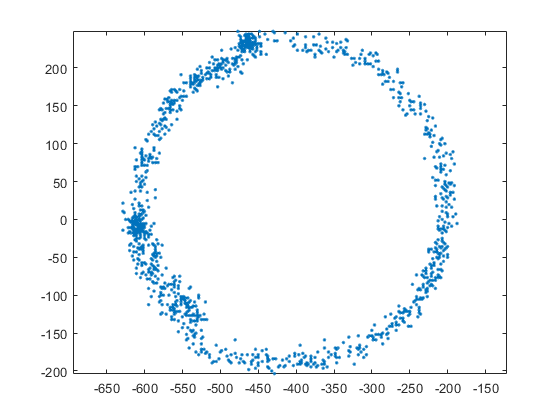

figure
plot(mag_2d_nice(:,1),mag_2d_nice(:,2), '.');
axis equal;

Furthermore, if we have some magnetisable material close (e.g.: wires, chassis of the device we are bulding - in this case emulated by a handful of nuts), the distortion of the circle into an elipse occurs.

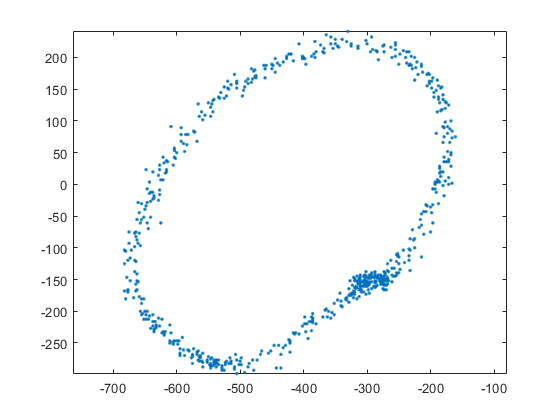

plot(mag_2d(:,1),mag_2d(:,2), '.');
axis equal;

To compensate for this, we must find the linear transformation, that brings the elipse back into the circle. To do this, first we have to find the parameters of the elipse that it describes - luckily, it can be effectively done with a simple least squares method.

#### Fitting an elipse - most general way

An elipse is defined as the set of points, that have equal distance from two given points (called the focal points), $A$ and $B$ on the plane. However, it is often more convinient, to parameterize it with it's center point, and the length of the semi-major axis, and semi-minor axis. With this parameterization, the equation of an elipse can be written in the simplest form as:


$$\frac{x^2}{a^2} + \frac{y^2}{b^2} = 1$$


Where:

- x, y: free variables

- a, b: length of the two semi axis (their value decides which is major and minor)

In this case, the center point of the elipse is the origin. If we want to change that, we have to introduce an offset to the $x$ and $y$ coordinates, so the equation becomes:


$$\frac{(x - h)^2}{a^2} + \frac{(y - k)^2}{b^2} = 1$$


Where:

- h, k: coordinates of the center point

This elipse can be anywhere, but it's axis are always parallel to the $x$ and $y$ axis of the coordinate frame. We can easily add this to the equation if we think about the rotation matrix in 2d:


$$\left[\matrix{x_{rot} \cr y_{rot}}\right] = \left[ \matrix{cos(\alpha) & sin(\alpha) \cr -sin(\alpha) & cos(\alpha)} \right]\left[ \matrix{x \cr y} \right]$$


If we resolve the matrix multiplication and apply it to the equation we will have:


$$\frac{(cos(\alpha)(x-h) + sin(\alpha)(y - k))^2}{a^2} + \frac{(sin(\alpha)(x-h) - cos(\alpha)(y - k))^2}{b^2} = 1$$


If we break up the brackets we can get a quadratic form (meaning that the variables are at max 2nd order), each monomial will get a constant multiplier, as:


$$Ax^2 + Bxy + Cy^2 + Dx + Ey + F=0$$


Where:

- 
$$A = \frac{cos^2(\alpha)}{a^2} + \frac{sin^2(\alpha)}{b^2}$$


- 
$$B = \frac{cos(2\alpha)}{a^2} - \frac{sin(2\alpha)}{b^2}$$


- 
$$C = \frac{sin^2(\alpha)}{a^2} + \frac{cos^2(\alpha)}{b^2}$$


- 
$$D = -\frac{2cos^2(\alpha)h}{a^2} - \frac{sin(2\alpha)k}{a^2} - \frac{2sin^2(\alpha)h}{b^2} + \frac{sin(2\alpha)k}{b^2}$$


- 
$$E = -\frac{sin(2\alpha)h}{a^2} - \frac{2sin^2(\alpha)k}{a^2} + \frac{sin(2\alpha)h}{b^2} - \frac{2cos^2(\alpha)k}{b^2}$$


- 
$$F = \frac{cos^2(\alpha)h^2}{a^2} + \frac{sin(2\alpha)hk}{a^2} + \frac{sin^2(\alpha)k^2}{a^2} + \frac{sin^2(\alpha)h^2}{b^2} - \frac{sin(2\alpha)hk}{b^2} + \frac{cos^2(\alpha)k^2}{b^2}-1$$


This is called the conic form of the ellipse equation. (Conic sections - hyperbole, parabole, ellipse - can be written in such a form, in general fitting this needs to be accounted).

We have measurements of $x$ and $y$ of this equation, thus we can create the following system of linear equations to write the parameter estimation:


$$\left[ \matrix{x^2_1 & x_1y_1 & y_1^2 & x_1 & y_1 & 1 \cr x^2_2 & x_2y_2 & y_2^2 & x_2 & y_2 & 1 \cr & & ... & & \cr x^2_n & x_ny_n & y_n^2 & x_n & y_n & 1}\right]\left[ \matrix{A \cr B \cr C \cr D \cr E \cr F}\right] = 0$$


Which can be written with $M$ as the measurement matrix and $p$ as the parameter vector. Keep in mind that $M$ is known from the measurements, and we are looking for $p$:


$$Mp=0$$


This is a homogeneous linear equation (because the right side is 0), which means it cannot be solved simply with the pseudo-inverse ($p = M^+0$), because that would give $p=0$, which has no value for us. If we make the restriction $\left| p \right| = 1$, the estimation can be done using the Singular-Value-Decomposition of M, and taking the last column of $V$ as $p$:


$$svd(M) = UDV^T$$



$$V = [v_1, v_2, ... v_m]$$



$$p = v_m$$


From the parameters $p = \left[ \matrix{A \cr B \cr C \cr D \cr E \cr F} \right]$ we can calculate the standard parameters of an ellipse, as the following:


$$A_{Q} = \left[ \matrix{A & B/2 & D/2 \cr B/2 & C & E/2 \cr D/2 & E/2 & F}\right]$$



$$A_{33} = A_{Q,1-2, 1-2} = \left[ \matrix{A & B/2 \cr B/2 & C} \right]$$



$$\lambda_1, \lambda_2 = eig(A_{33})$$


- 
$$\left[ \matrix{h \cr k} \right] = \left[ \matrix{ \frac{BE - 2CD}{4AC - B^2} \cr \frac{DB - 2AE}{4AC - B^2}} \right]$$


- $a,b = \sqrt{-\frac{det(A_Q)}{det(A_{33})\lambda_{1,2}}}$ (not that it has to be examined which values is greater to decide whihc is the major and minor axis)

- 
$$\alpha = tan^{-1}\left(\frac{C-A}{B} + \frac{\sqrt{(A-C)^2+ B^2}}{B}\right)$$


(source: https://en.wikipedia.org/wiki/Matrix_representation_of_conic_sections, https://math.stackexchange.com/questions/1839510/how-to-get-the-correct-angle-of-the-ellipse-after-approximation/1840050#1840050)

x = mag_2d(:,1);
y = mag_2d(:,2);
A = [x.^2, x.*y, y.^2, x, y, ones(size(x))];
[U,D,V] = svd(A);
c = V(:,6);

A = c(1);
B = c(2);
C = c(3);
D = c(4);
E = c(5);
F = c(6);

el = ellipse_conic2std(A,B,C,D,E,F);

Ellipse


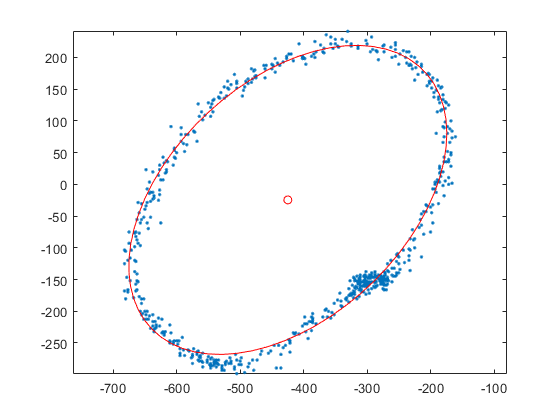

a = el(1);
b = el(2);
x_c = el(3);
y_c = el(4);
alpha = el(5);

th = [0:0.1:2*pi+0.1];
el = [cos(alpha), sin(alpha); -sin(alpha), cos(alpha)] * [a, 0; 0, b] * [sin(th); cos(th)] + [x_c;y_c];

plot(mag_2d(:,1),mag_2d(:,2), '.');
axis equal;
hold on;
plot(x_c, y_c,'ro');
plot(el(1,:),el(2,:),'r');
hold off;

#### Calibration

Calibration means, that we want to transform the measurements to have a shape of a circle. This can be done simply by the following linear transformations:

- shift to the origin

- apply rotation

- scale aling axis


$$\left[ \matrix{x' \cr y'} \right] = \left[ \matrix{1/a & 0 \cr 0 & 1/b} \right] Rot_{-\alpha} \left(\left[ \matrix{x - h \cr y - k} \right]\right)$$


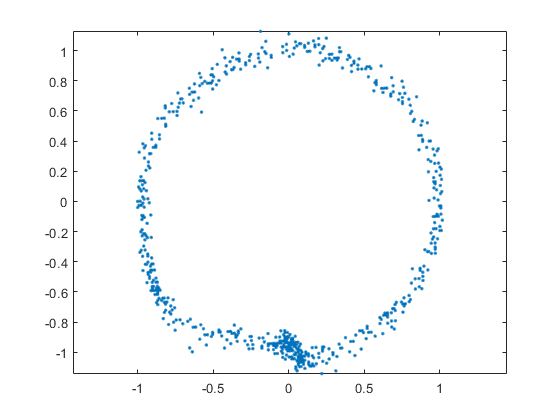

mag_2d_calib = [1/a, 0; 0, 1/b] * [cos(-alpha), sin(-alpha); -sin(-alpha), cos(-alpha)] * [mag_2d(:,1:2)' - [x_c; y_c]];
plot(mag_2d_calib(1,:), mag_2d_calib(2,:),'.');
axis equal;

### 3D